loadspice(['Project1WC.txt'])

clf;
hold on;

% Period values for each case
periods = []


periods =

     []



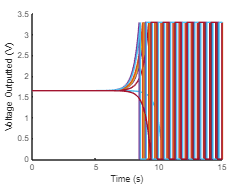


for index = 1:21
    n002_this = cell2mat(n002(index)); % Voltage values
    time_this = cell2mat(time(index)); % Corresponding time values

    % Plot Voltage v. time for this case
    plot(time_this, n002_this)
    xlabel("Time (s)")
    ylabel("Voltage Outputted (V)")

    first_min = 0;
    first_min_index = 0;
    first_max = 0;
    first_max_index = 0;
    second_min = 0;

    % For each voltage value, check if the value is the first "low" of the
    % data
    for point = 1:length(n002_this)
        if n002_this(point) < 0.001
            first_min = time_this(point);
            first_min_index = point;
            break
        end
    end

    % For points after the first "low", check if the voltage is the first
    % "high" of the data
    for sec_point = first_min_index:length(n002_this)
        if n002_this(sec_point) > 3.2
            first_max = time_this(sec_point);
            first_max_index = sec_point;
            break
        end 
    end

    % For points after the first "high", check if the voltage has dropped
    % back to "low"
    for third_point = first_max_index:length(n002_this)
        if n002_this(third_point) < 0.001
            second_min = time_this(third_point);
            break
        end
    end


    period = (second_min - first_min);
    periods = [periods, period];
end